# Drone Arm 2 FEA

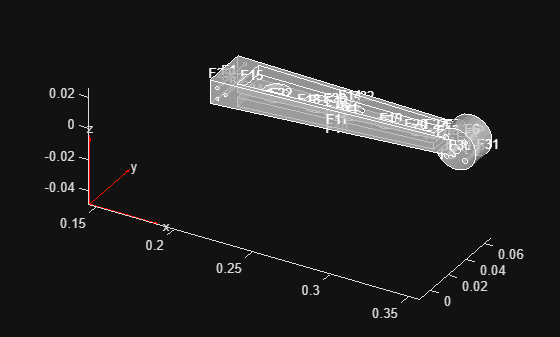

clear
clc

%----- Load in Important Data / Create Mesh / Known Values -----%
prop = load('droneArmMaterials.mat');

% Material Number (n)
% n=1, Carbon Fiber Composite
% n=2, Aluminum Alloy
% n=3, Fiberglass Composite
% n=4, PLA Plastic
% n=5, ABS Plastic
% n=6, Wood (Birch)

% Import CAD file
gm = importGeometry("drone_circles_arm1.stl"); %Note: CAD model is flipped on it's side (+y is up)
gm = scale(gm,0.001);                          %Scaled down geometry to keep units in (m)
pdegplot(gm,FaceLabels="on",FaceAlpha=0.7)    % <---Use to visualize Geometry (not needed)


% Create mesh of CAD file
md = femodel(AnalysisType="structuralStatic",Geometry=gm);
md = generateMesh(md, Hmin=0.001);
%pdemesh(md)   % <---Use to visualize mesh (not needed)

% Known/Set Values
n = 1;                                                  %Material Number
TotalA = prop.materials(n).rho_kg_m3*0.00002933*-9.8;   %Arm Weight, F(g) = p*V*a(g) (N)
TotalT = 1 * 9.8;                                       %Thrust force, F(t) = m*a(+g) (N)
TotalW = 1 * -9.8;                                      %Body Weight, F(g) = m*a(g) (N)
TotalP = 0.5 * -9.8;                                    %Min Payload Weight, F(g) = m*a(g) (N)
AreaProp = pi*(0.026/2)^2;                              %Area of propeller mount (m^2)
AreaBottom = 0.150*0.0150;                              %Area underneath Drone Arm (m^2)






%----- Set Conditions -----%
% Add in Material properties onto Mesh
md.MaterialProperties = materialProperties(...
YoungsModulus=prop.materials(n).E_Pa,... 
MassDensity=prop.materials(n).rho_kg_m3,... 
PoissonsRatio=prop.materials(n).nu);


% LOADS (aka conditions):
% Add in constraint (End of Drone Arm)
md.FaceBC(29) = faceBC(Constraint="fixed");

% Factor in weight of drone arm
md.CellLoad = cellLoad(Gravity=[0 -9.8 0]);  % Gravity applied in y instead of z

% Factor in thrust force of propeller (1kg per prop)
TPressure = TotalT/AreaProp; %Pressure of Thrust 
md.FaceLoad(30) = faceLoad(SurfaceTraction = [0 TPressure 0]);

% Factor in weight of drone components in body (1kg)
WOnArm = TotalW/4; %Assuming center of mass is at middle (N) and weight is divided equally per arm
WPressure = WOnArm/AreaBottom;
md.FaceLoad(11) = faceLoad(SurfaceTraction = [0 WPressure 0]);

% Factor in Payload weight (min of 0.5kg)
POnArm = TotalP/4;
PPressure = POnArm/AreaBottom;
md.FaceLoad(11) = faceLoad(SurfaceTraction = [0 PPressure 0]);

% Factor in Additional Payload while keeping thrust to weight ratio of 2:1
AddP = -1*(((4*TotalT)/2)+TotalW+TotalP+(TotalA*4));
TotalAP = AddP/4;
APPressure = TotalAP/AreaBottom;
md.FaceLoad(11) = faceLoad(SurfaceTraction = [0 APPressure 0]);



%---- Calculate FEA Solution / Analyze Solutions / Visual -----%
% Solve FEA
sol = solve(md);

% Calculating max displacement (in y direction)
maxDeflection = max(sol.Displacement.uy)

maxDeflection = 6.1076e-05


% Calculating max Von Mises Stress
maxVonStress = max(sol.VonMisesStress)

maxVonStress = 1.1807e+06


% Factor of Safety (How close to plastic deformation (yield strength))
FoS = prop.materials(n).yieldStrength_Pa/maxVonStress

FoS = 67.7559





% Visual of Results (x,y,z displacements and Von Mises Stress)

% Data to visualize
meshData = sol.Mesh;
nodalData = sol.Displacement.Magnitude;
deformationData = sol.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",457.5338, ...
    "ColorLimits",[0 8.05e-05]);

% Clear temporary variables
clearvars meshData nodalData deformationData